# Who is That?

This example uses transfer learning to train a deep network that can classify images of faces.

## Get training images

faceds = imageDatastore("Faces","IncludeSubfolders",true,"LabelSource","foldernames");

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(faceds,0.5,"randomized");

Determine the number of face categories

numClasses = numel(categories(faceds.Labels));

## Create a network by modifying AlexNet

Get the layers from AlexNet

deepnet = alexnet;
lgraph = layerGraph(deepnet)

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


Modify the classification and output layers

newFc = fullyConnectedLayer(2,"Name","new_fc")

newFc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"fc8",newFc)

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


newOut = classificationLayer("Name","new_out")

newOut =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
    ClassWeights: 'none'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"output",newOut)

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


## Set training algorithm options

Lower the learning rate for transfer learning

options = trainingOptions("sgdm","InitialLearnRate", 0.001);

## Perform training

[facenet,info] = trainNetwork(trainImgs, lgraph, options);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       46.09% |       2.0353 |          0.0010 |
|      30 |          30 |       00:00:50 |      100.00% |   7.3629e-06 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


## Use the trained network to classify test images

testpreds = classify(facenet,testImgs);

## Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

ans = 0.9933

Visualize the confusion matrix

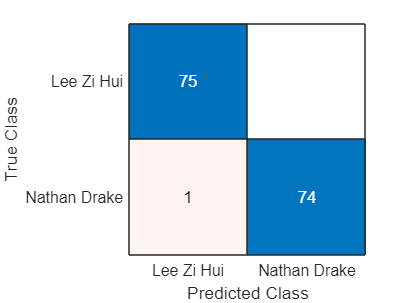

confusionchart(testImgs.Labels,testpreds);